# Estimation of a Constant Using a Kalman Filter

## Introduction

- Suppose we acquire measurements of a quantity that we know to be **constant**, or at most admits of **step changes**. 

- The *observations* we have are affected by *measurement noise* (as usual, the measurement sensor introduces noise into the measurement result). 

- How can we use a Kalman filter as an optimal predictor of the (constant) quantity?

## The Model

What could be the description in **state equations** of the dynamics of a **variable** that is actually **constant** (thus **NOT varying in time**)?

If we denote by $x(t)$ the state variable at the time instant $t$, representing the constant to be estimated, the dynamics of this state variable over time is:


$$\left\{
\begin{array}{rcl}
x(t+1) &=& \mathrm{?} \\
y(t) &=& x(t) + v_2(t)
\end{array}
\right. \qquad v_2(\cdot) \sim \mathrm{WGN} \left(0,\, \lambda_2^2\right)$$


**Model:**


$$\left\{
\begin{array}{rcl}
x(t+1) &=& x(t) + v_1(t) \\
y(t) &=& x(t) + v_2(t)
\end{array}
\right. \qquad v_2(\cdot) \sim \mathrm{WGN} \left(0,\, \lambda_2^2\right)$$


Dopo un po'lo stimatore si adatta nel caso in cui la costante dovesse cambiare. La stima ai minimi quadrati stimerebbe una linea a meta` tra lo scalino, mentre lo stimatore di Kalman segue il cambiamento.

## The Data  

### Initialization

clear
clc
close all

load L14_Kalman_ConstantEstimationDATA.mat
% y <--> the measurements of the state variable, i.e. the constant to be
%        estimated 
% DeltaT <--> the sampling period [s]

N = numel(y); % how many data?
timeSteps = (0:N-1).*DeltaT; % the sampling time instants
whos

  Name           Size                Bytes  Class     Attributes

  DeltaT         1x1                     8  double              
  N              1x1                     8  double              
  timeSteps      1x36000            288000  double              
  y              1x36000            288000  double              



### Plotting the Measurements

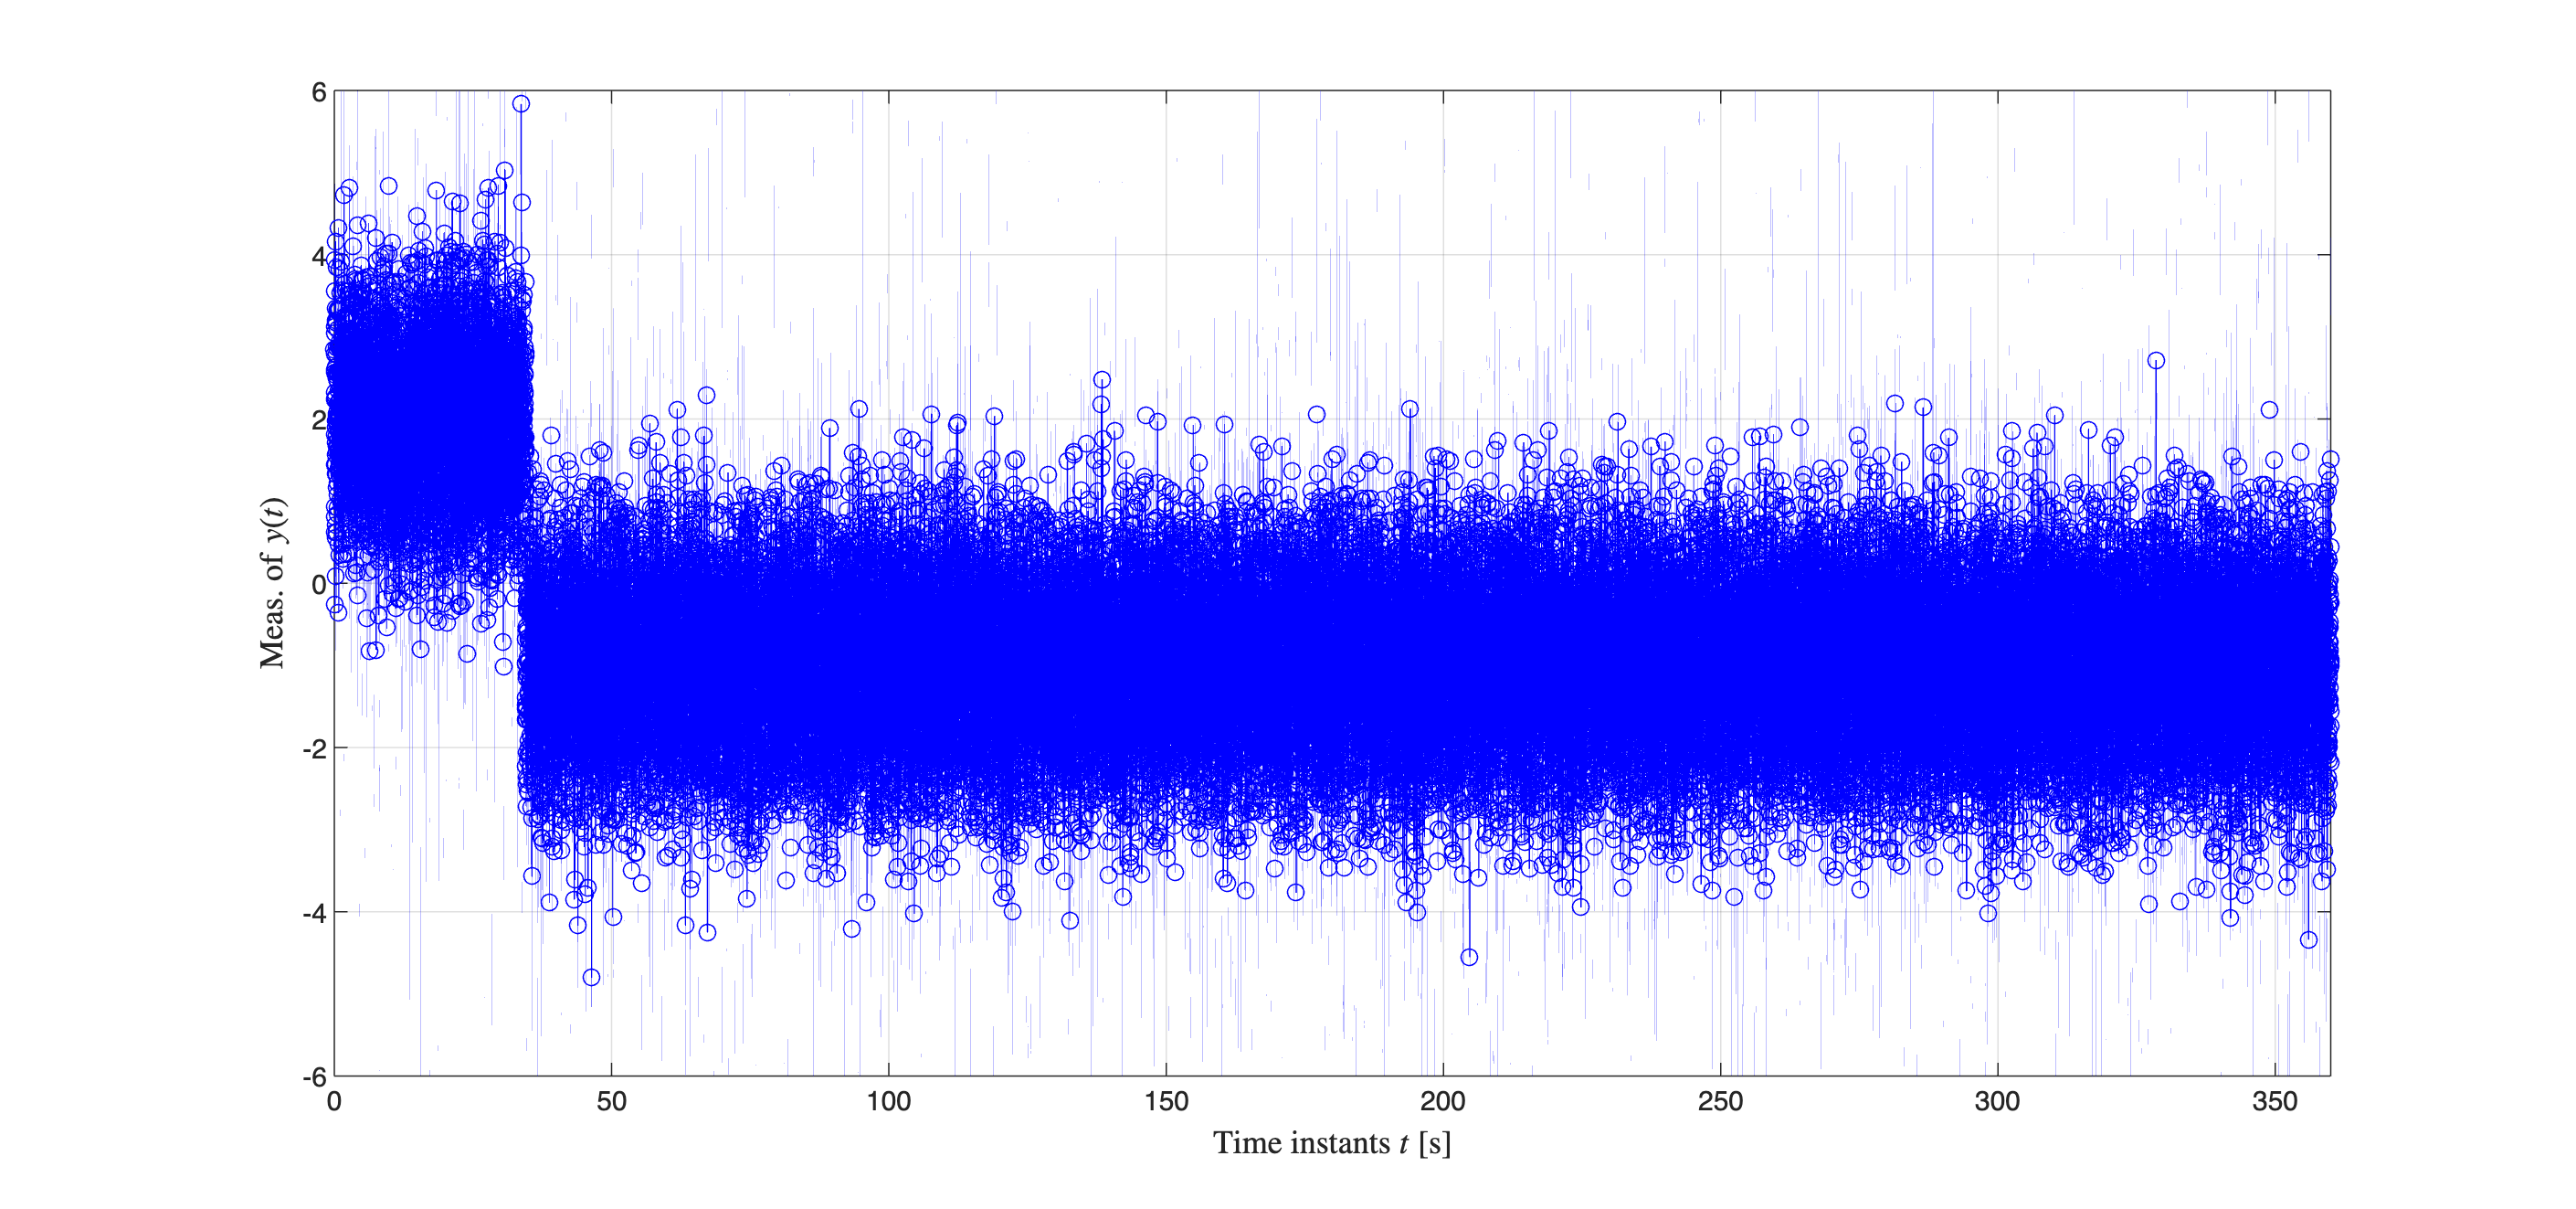

figure('Units','normalized','Position',[0.1, 0.1, 0.9, 0.75]);

plot(timeSteps, y,'bo-'); 
grid on; zoom on;
xlim([min(timeSteps), max(timeSteps)]);
xlabel('Time instants $t$ [s]', 'Interpreter','latex','FontSize',12);
ylabel('Meas. of $y(t)$',  'Interpreter','latex','FontSize',12);

matA = 1;
matB = 0;
matC = 1;
matD = 0;